% === PARAMETERS ===
messages_per_day = 10;      % הודעות ליום
tokens_per_message = 350;   % טוקנים להודעה (תלוי אורך ומורכבות)
days_per_month = 30;        % ימי שימוש בחודש
months = 1:12;              % מספר חודשי שימוש לחישוב גרפי

% === MODELS AND PRICES PER 1K TOKENS (USD) ===
models = {'GPT-3.5 Turbo', 'GPT-4 Turbo', 'Claude 3 Opus', 'Mistral Medium', 'Gemini 1.5 Pro'};
prices_per_1k = [0.0005, 0.01, 0.015, 0.002, 0.007];

% === CALCULATION ===
tokens_per_month = messages_per_day * tokens_per_message * days_per_month;
tokens_per_month_thousands = tokens_per_month / 1000;

% עלות חודשית ראשונית
monthly_costs = tokens_per_month_thousands * prices_per_1k;

% חישוב עלות לכל חודש עבור כל מודל
costs_over_time = monthly_costs' * months;

% === DISPLAY RESULTS ===
disp('Estimated Monthly Costs (USD):');

Estimated Monthly Costs (USD):


T = table(models', monthly_costs', 'VariableNames', {'Model', 'Monthly_Cost_USD'});
disp(T);

          Model           Monthly_Cost_USD
    __________________    ________________

    {'GPT-3.5 Turbo' }         0.0525     
    {'GPT-4 Turbo'   }           1.05     
    {'Claude 3 Opus' }          1.575     
    {'Mistral Medium'}           0.21     
    {'Gemini 1.5 Pro'}          0.735     



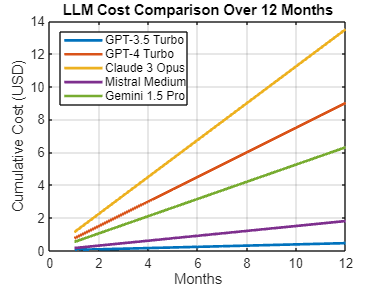


% === PLOT RESULTS ===
figure;
plot(months, costs_over_time, 'LineWidth', 2);
title('LLM Cost Comparison Over 12 Months');
xlabel('Months');
ylabel('Cumulative Cost (USD)');
legend(models, 'Location', 'northwest');
grid on;